# Lecture 9  Application of Matlab in Numerical Analysis III: Numerical Solution of Ordinary Differential Equations (ODE)

## **Mathematical Background**

### **Concept of **[ODE](https://en.wikipedia.org/wiki/Ordinary_differential_equation)

Briefly speaking, ODE is to solve for a single-variable function where we have the constraints (equations) between the function itself and its derivatives.

For instance, $\frac{\mathrm{dy}}{\mathrm{dx}}=y$ is the first order ODE, and one solution is $y=e^x$.   

$\frac{d^2 x}{{\mathrm{dt}}^2 }=-x$ is the second order ODE, and one solution is $x=\sin \left(t\right)$

Here we only focus on the initial-value problem of first order autonomous ODEs


$$\frac{\mathbf{dy}}{\mathrm{dt}}=\mathit{\mathbf{f}}\left(\mathit{\mathbf{y}}\right),\mathit{\mathbf{y}}\left(0\right)={\mathit{\mathbf{y}}}_0$$
 

Intuitive understanding (physical interpretation): y(t) is the location of particle at time t, and f(y) is the velocity at location y. The ODE describes the "physical law" of particle's movement, and the solution of ODE is indeed the trajectory of particle.

### **Numerical solutions of ODE**

Assume we patition the time interval $\left\lbrack 0,t_{\max } \right\rbrack$ equally as $0=t_0 <t_1 <\ldotp \ldotp \ldotp <t_N =t_{\max }$ with time step size $h=\frac{t_{\max } }{N}$ . The aim is to find as the numerical approximation to the true solution $y_1 \;{,y}_2 ,\ldotp \ldotp \ldotp {,y}_N$, where $y_k$ approximates $y\left(t_k \right)$

**The forward Euler method:** the velocity on R.H.S. is constant in each small time interval and can be replaced by the left-end value on interval,  and the derivative on L.H.S. can be approximated by forward difference scheme:


$$\frac{y_{k+1} -y_k }{h}=f\left(y_k \right)$$


And we have the recursive formula


$$y_{k+1} =y_k +h\;f\left(y_k \right)$$


## One-dimension case

***Example 1***: $\;\frac{\textrm{dx}}{\textrm{dt}}=-x,x\left(0\right)=1$, where the exact solution is $x\left(t\right)=e^{-t}$

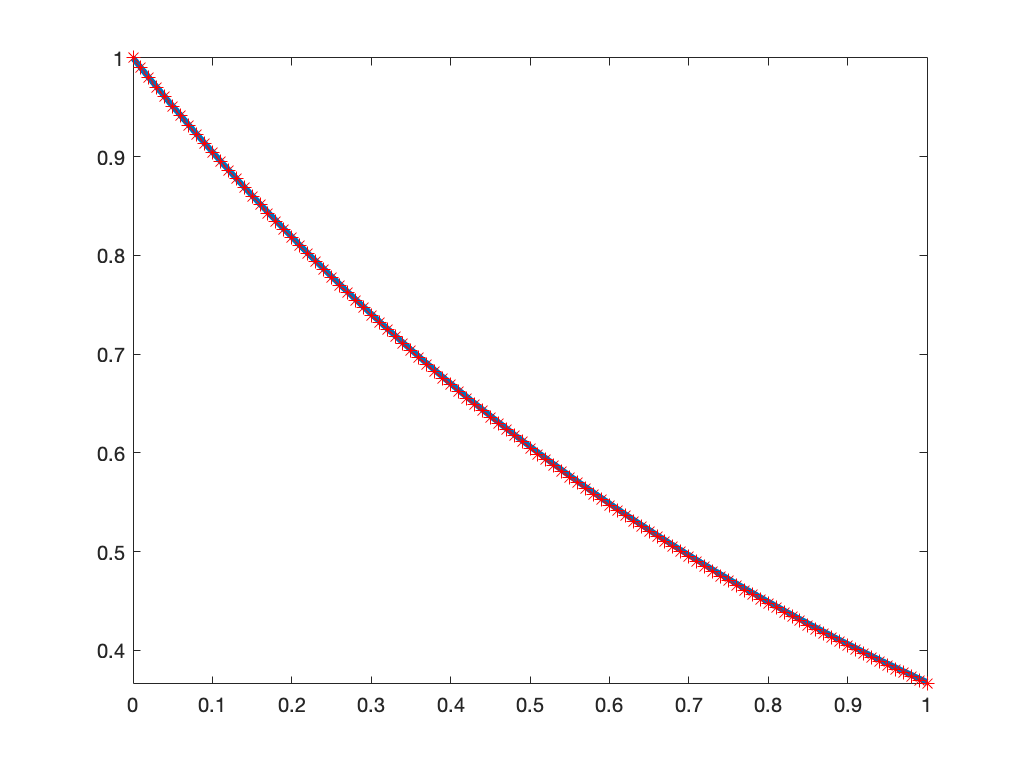


f = @(x) -x;
x0 = 1;
N = 100;
t_max = 1;
[t,x] = euler_forward(f, t_max, x0, N);
fplot(@(t)exp(-t),[0 1],'LineWidth',3.0)
hold on
plot(t,x,'r*')
hold off

***Example 2***:  [Logistic growth model](https://www.maa.org/press/periodicals/loci/joma/logistic-growth-model-background-logistic-modeling)

$\frac{\textrm{dP}}{\textrm{dt}}=\textrm{rP}\left(1-\frac{P}{K}\right)$ where r and K are two positive numbers (parameters).

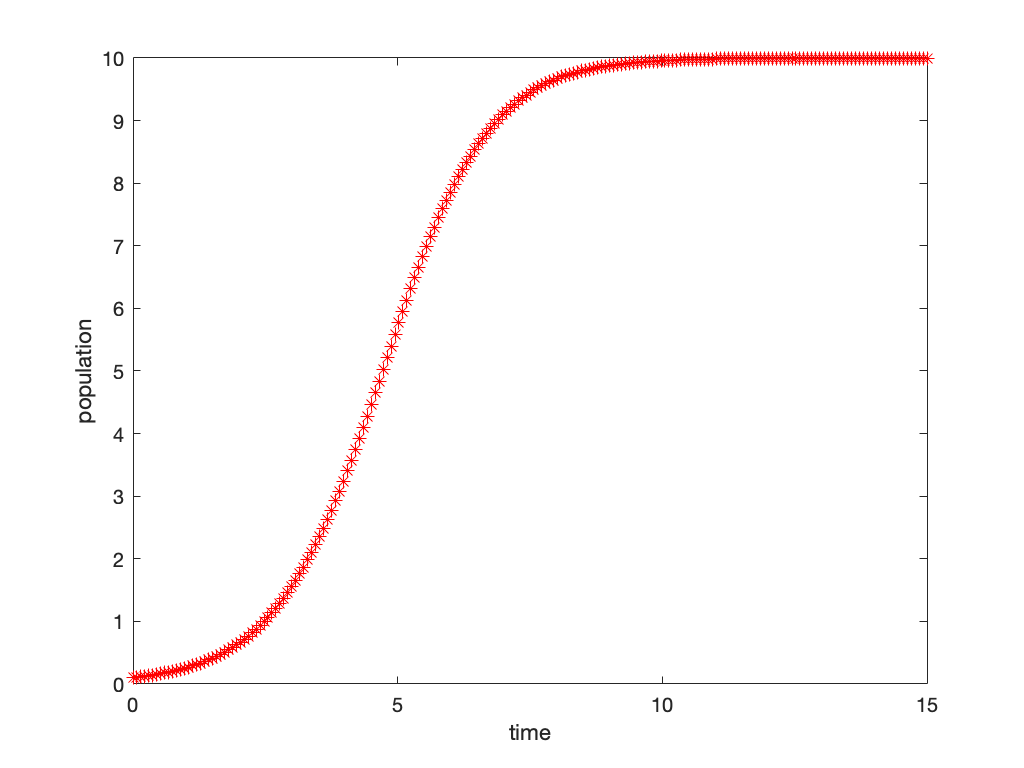

r = 1;
K = 10;
g = @(P) r*P*(1-P/K);

p0 = 0.1;

N = 200;
t_max = 15;
[t,p] = euler_forward(g, t_max, p0, N);
plot(t,p,'r*')
xlabel('time')
ylabel('population')

## High-dimension case

***Example 3***: Prey-Predator Equation which is also called [Lotka-Volterra Equation](https://en.wikipedia.org/wiki/Lotka%E2%80%93Volterra_equations)


$$\begin{array}{l}
\frac{\mathrm{dx}}{\mathrm{dt}}=\alpha \;x-\beta \;\mathrm{xy}\\
\frac{\mathrm{dy}}{\mathrm{dt}}=\delta \;\mathrm{xy}-\gamma \;y
\end{array}$$


x0 = [1;1]; %row vector

x0 =      1
     1


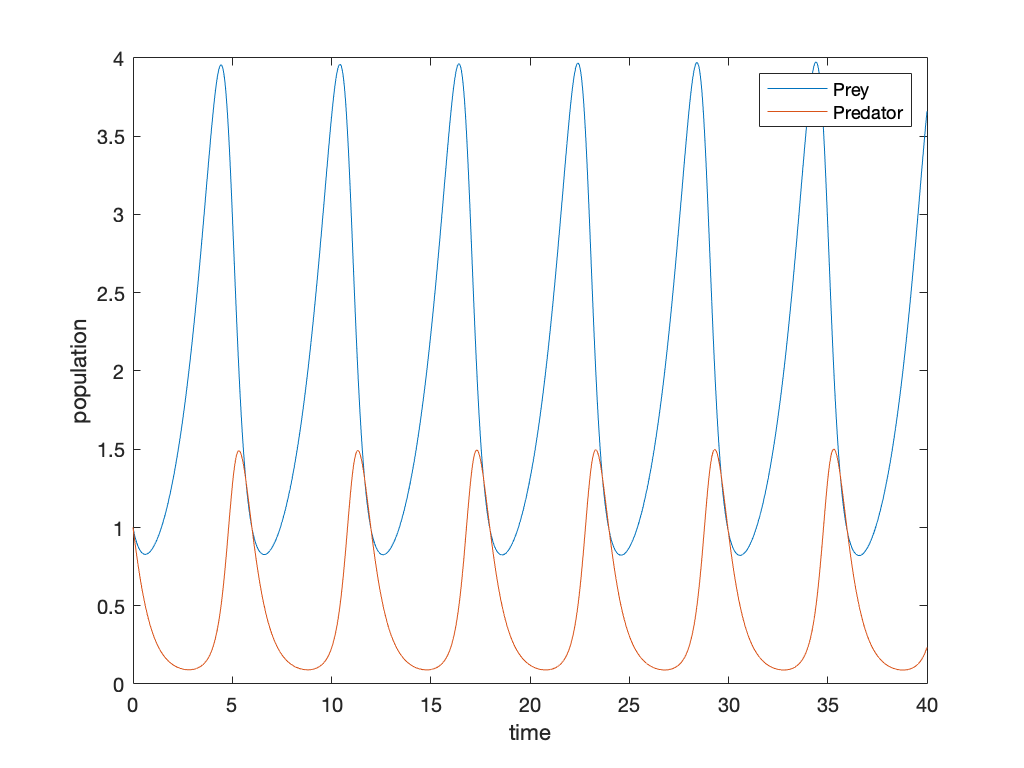

N = 1e5; %what about decrease N
t_max = 40;
[t,x] = euler_forward(@f_lv, t_max, x0, N);
plot(t,x)
xlabel('time')
ylabel('population')
legend('Prey','Predator')

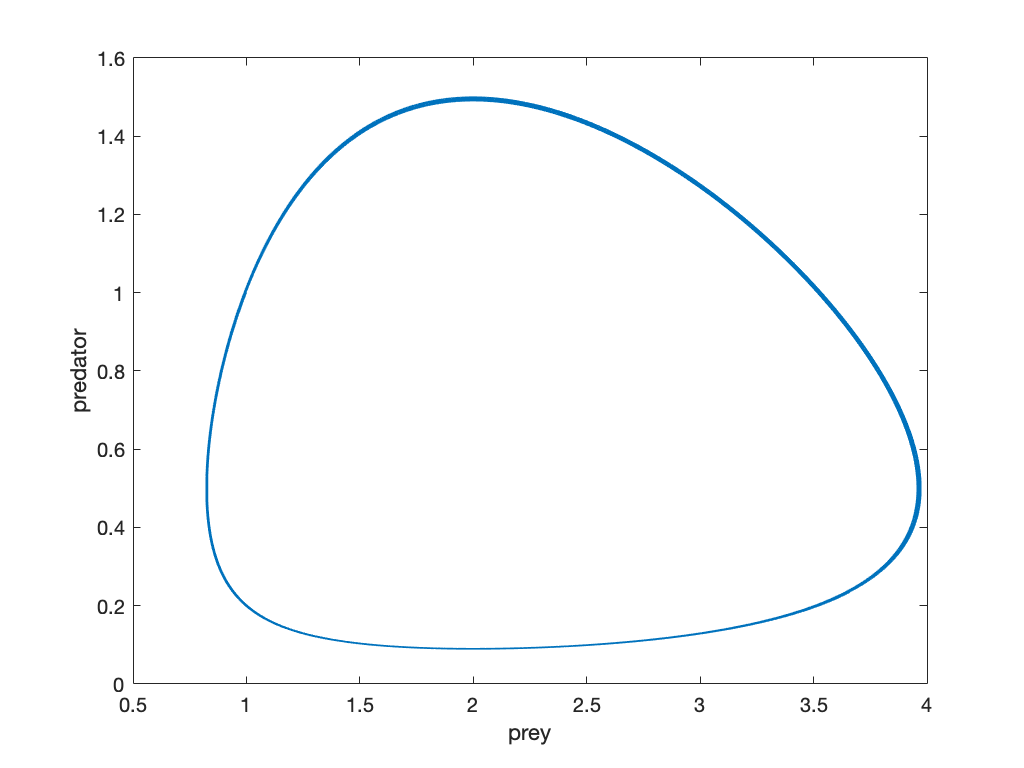

plot(x(1,:),x(2,:))
xlabel('prey')
ylabel('predator')

Exercise: change the initial value of y (predator) from 1 to 2 with stepsize 0.1, and see how the solution in phase plane changes.

Alternative ways to call functions with more flexible control of parameters in ODE

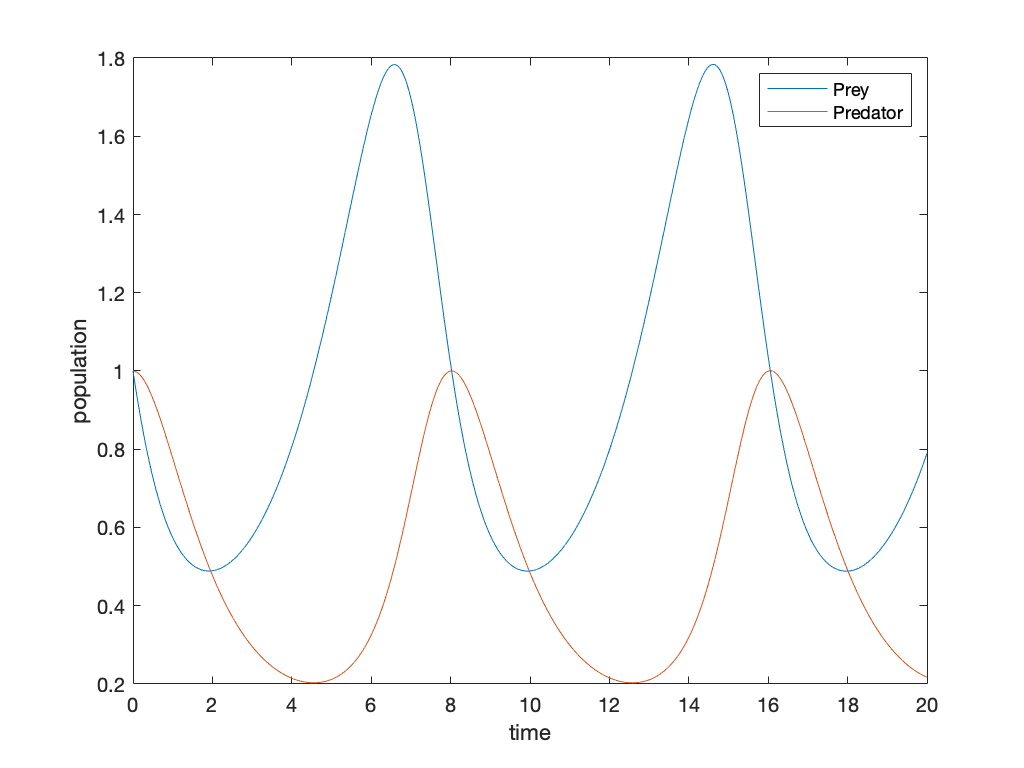


alpha = 2/3;
beta = 4/3;
gamma = 1;
delta = 1;


% alternative 1
f= @(x)f_lv_new(x,alpha,beta,gamma,delta); %create the function handle w.r.t variable x

% alternative 2
%f = @(x)[alpha*x(1)-beta*x(1)*x(2);delta*x(1)*x(2)-gamma*x(2)]; % create
%the function handle directly

N = 1e5; %what about decrease N
t_max = 20;
[t,x] = euler_forward(f, t_max, x0, N);
plot(t,x)
xlabel('time')
ylabel('population')
legend('Prey','Predator')

function [t,x] = euler_forward(f, t_max, x0, N)

    x = zeros(length(x0),N+1);
    x(:,1) = x0;
    h = t_max/N; %step size
    t = 0:h:t_max;
    
    for k = 1:N
        x(:, k+1) = x(:,k)+h*f(x(:,k));
    end

end

function output = f_lv (x)
    alpha = 2/3;
    beta = 4/3;
    gamma = 2;
    delta = 1;
    output = zeros(2,1);
    output(1) = alpha*x(1)-beta*x(1)*x(2);
    output(2) = delta*x(1)*x(2)-gamma*x(2);
end

function output = f_lv_new (x,alpha,beta,gamma,delta)
    output = zeros(2,1);
    output(1) = alpha*x(1)-beta*x(1)*x(2);
    output(2) = delta*x(1)*x(2)-gamma*x(2);
end